# Qiita API でデータ抽出

Qiita は Qiita API を公開しており、様々なデータ抽出を可能にしてくれています。ここでは MATLAB / Simulink タグの投稿状況を見てみます。

## 記事データ取得

matlab タグ、simulink タグがついた全記事を取得します。ご自身の accessToken を取得してお試しください。

clear
loadFlag = false;

if loadFlag || ~exist('allArticles.mat','file')
    % アクセストークン使用（ご自身の accessToken を取得してお試しください）
    accessToken = 'Bearer xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx';
    opts = weboptions('HeaderFields',{'Authorization',accessToken});
    % opts = weboptions; % アクセストークン使用しない場合
    
    page = 1;
    data = [];
    tags = ["matlab","simulink"];
    for ii=1:2 % 2つの tag をループで処理
        page = 1;
        while true
            % 1 request 辺りの上限が 100 件なので繰り返し処理
            url = "https://qiita.com/api/v2/tags/" + tags(ii) + "/items?page="+page+"&per_page=100";
            tmp = webread(url,opts);
            if isempty(tmp)
                break;
            end
            data = [data;tmp]; %#ok<AGROW> 
            page = page + 1;
        end
    end
    % テーブル型に変更
    data = struct2table(data);
    
    % 念のため unique で重複回避
    [~,ia,~] = unique(data.id);
    data = data(ia,:);
    save('allArticles.mat','data')
else
    load allArticles.mat %#ok<UNRCH> 
end

## データ確認

冒頭の8アイテムを表示してみます。変数として `title`、`rendered_body` や `created_at`、`like_count` など全16変数が取れていることが分かります。 

head(data)

ans = 8×16 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

## 時系列データ集計

投稿数の推移を集計するために `timetable` 型を活用します。

作成日時 `created_at` は `datetime` 型にします。フォーマットに注目。

created_at = datetime(vertcat(data.created_at),...
    'InputFormat', "uuuu-MM-dd'T'HH:mm:ss'+09:00");
tData = table2timetable(data(:,{'title','user','likes_count','tags','url'}),'RowTimes', created_at);

ここではタイトル、ユーザー名、いいね数、タグ、Page URL だけを残しておきます。`url` はセルの中に `char` で入っている状態なので簡単ですが、`user` はセルに入った構造体 `tag` はセルに入った構造体ベクトルなので少しややこしい。

具体的にはこんな感じ・・

tData.user(1)

ans = フィールドをもつ struct :
            description: '大学時代はC言語でポインターを駆使して画像処理、時系列データ解析を行い、SIerでシステム設計、ソフトウェア開発(主にJavaScriptのフロントエンド)を行い、現在は外資系IT企業でエンジニアをやっています。HTML/JavaScript、PHP、Java、.NET、MATLAB、SQLなどなど、色々なプログラム言語を使うので、言語の違いを楽しみながら日々バリバリ書いています。'
            facebook_id: ''
        followees_count: 3
        followers_count: 7
      github_login_name: []
                     id: 'Alberobellojiro'
            items_count: 3
            linkedin_id: ''
               location: ''
                   name: ''
           organization: ''
           permanent_id: 254990
      profile_image_url: 'https://qiita-image-store.s3.amazonaws.com/0/254990/profile-images/1525506429'
              team_only: 0
    twitter_screen_name: []
            website_url: ''


tData.tags{1}

ans = フィールドをもつ 2×1 の struct 配列:
    name
    versions


ここでは `timetable` 型の各行に関数を適用する `rowfun` 関数を使ってみます。`tags` については構造体の `name` メンバーだけを `string` 型のベクトルに変換など。諦めて for ループで回した方が可読性がよいかもしれませんね。

tData.url = string(tData.url);
tData.user = rowfun(@(x) string(x.id),tData,'InputVariable','user','ExtractCellContents',true,'OutputFormat','uniform');
tData.tags = rowfun(@(x) string({x.name}),tData,'InputVariable','tags','ExtractCellContents',true,'SeparateInputs',true,'OutputFormat','cell');

結果こんな感じです。ついでに時系列順に並べておきましょう。

tData = sortrows(tData,'Time','descend');
head(tData)

ans = 8×5 timetable
            Time                                                title                                              user           likes_count        tags                                     url                              
    ____________________    _____________________________________________________________________________    _________________    ___________    ____________    ______________________________________________________________

    17/Apr/2020 10:38:37    {'Matlabで時系列データを周波数解析する'                                          }    "hogemaccho"              1         {1×2 string}    "https://qiita.com/hogemaccho/items/91d290fccdaec0e5e5ea"     
    17/Apr/2020 09:22:29    {'2.1.2 画像・3次元ボリュームデータ・医用画像(DICOM/NIfTI)の表示'                   }    "tohruk"                  3         {1×5 string}    "https://qiita.com/tohruk/items/43b3dd1451b99b99cde3"         
    16/Apr/2020 08:38:00    {'5.6.6 ディープラーニング：点群データのサポート'                                  }    "tohruk"  

## 月間投稿数推移

月間投稿数を集計してみます。ここは `retime` の出番です。

と、新しい時間ステップ `newTimeStep` と集計方法 `method` を指定します。月間投稿数であれば

tmp = retime(tData(:,'title'),'monthly','count');

棒グラフ表示しますと、2019 年後半から急増していることは分かりますね。2019年12月のピークはアドベントカレンダーの影響です。

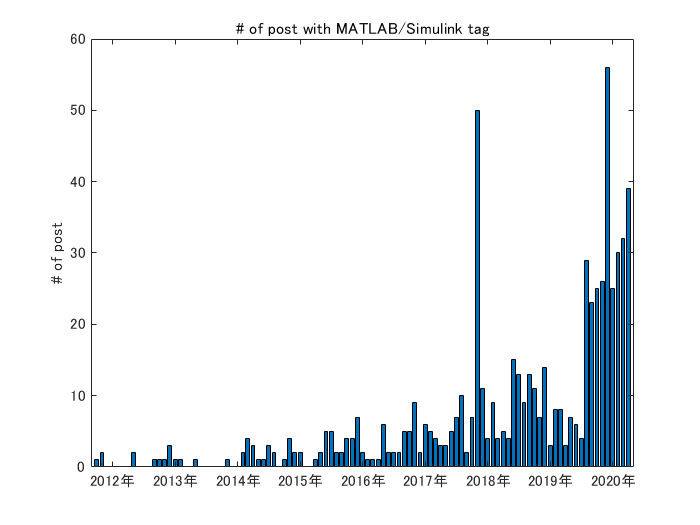

bar(tmp.Time,tmp.title)
title('# of post with MATLAB/Simulink tag')
ylabel('# of post')

## OnThisDay

過去の「この日」に投稿された記事・・という順に並べてみます。たとえば過去の投稿をなつかしんだり。。

まず `ymd` 関数で日付を年、月、日に分解します。

% get the month/day of when the post is created
[y,m,d] = ymd(tData.Time);

そして年数を引く・・と

daysofYear = tData.Time - years(y);
[tData.Time(1), daysofYear(1)]

ans = 1×2 の datetime 配列
   17/Apr/2020 10:38:37   17/Apr/0000 02:14:37


うまくいきません。年によって実際の長さが違うから・・だと思います。年数だけ引く場合は `calyears` を使います。

daysofYear = tData.Time - calyears(y);
[tData.Time(1), daysofYear(1)]

ans = 1×2 の datetime 配列
   17/Apr/2020 10:38:37   17/Apr/0000 10:38:37


キッチリ年数分引けていますね。ということで、記事の年齢（何年前に投稿された記事か）をデータに加えて、1月から順に並べておきます。

% How old the posts are
tData.howOld = 2020 - y;
% sort by the days of the year
[~,idx] = sort(daysofYear,'ascend');
tData = tData(idx,:);
head(tData)

ans = 8×6 timetable
            Time                                        title                                     user          likes_count        tags                                    url                                 howOld
    ____________________    _____________________________________________________________    _______________    ___________    ____________    ____________________________________________________________    ______

    01/Jan/2017 04:17:02    {'MATLAB2015b(32bit版)でpointgrayのサポートパッケージが動かない話'}    "nomper"                0         {1×4 string}    "https://qiita.com/nomper/items/45e47434f746d852acd4"             3   
    02/Jan/2020 06:49:23    {'マハラノビス距離の説明とmatlabでの実験'                         }    "pengin6"              16         {["matlab"]}    "https://qiita.com/pengin6/items/467287eef6d711e1313a"            0   
    03/Jan/2020 11:43:04    {'Simulink API (4) Simulink APIを使う"目的"と前回の続き'        }    "stozaki"               4         {1×3 string}    "https://

## 投稿された曜日

曜日については

の構文でとれます。

tData.dayofWeek = day(tData.Time,'name');

曜日別に投稿数を確認してみます。

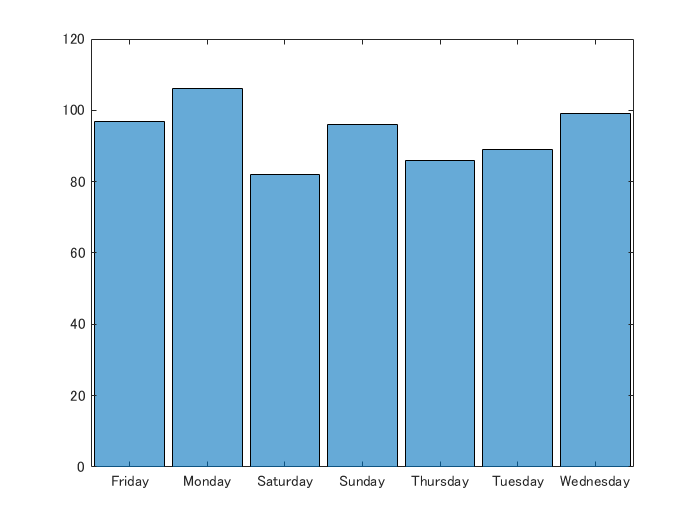

histogram(categorical(tData.dayofWeek));

あんまり差がないですね。一応月曜日が一番多いですね。

表示がアルファベット順なので修正。

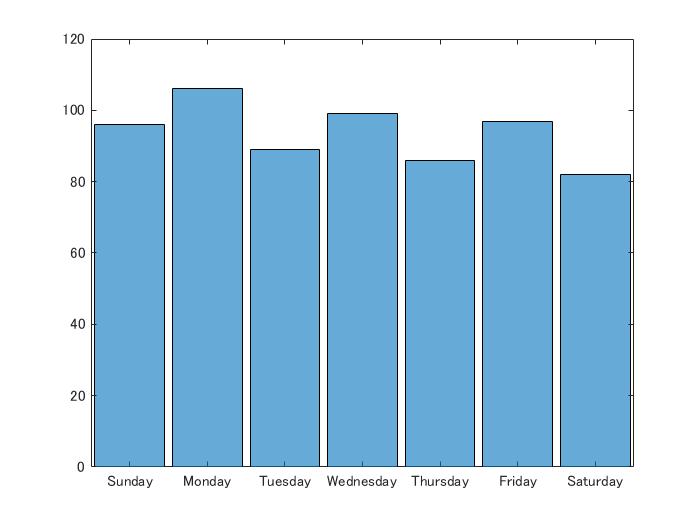

histogram(categorical(tData.dayofWeek),["Sunday","Monday","Tuesday","Wednesday","Thursday","Friday","Saturday"]);